Data Science (Prof. Neff)                Versuchsdatum 28.10.2020
Bestimmung der Viskosität von Spülmittel
Gruppe 6:    Benjamin Hamm (2060696), Jan Klotter (2060690),
Anna Kuhn (2051063), Michael Schulze (2061282)

Rohdaten der einzelnen Gruppenmitglieder


% Aufgabe 1
%Büroklammern
data_buero = readtable('Lebensdauer_Bueroklammer (1).csv')

data_buero = 75×1 table
    Zyklen
    ______

     9    
    61    
     3    
     2    
     4    
     7    
    25    
    16    
    97    
     4    
     5    
    50    
     2    
     2    
    13    
    17    



% Bueroklammern b)
pd_norm_buero = fitdist(data_buero.Zyklen,'Normal')

pd_norm_buero =   NormalDistribution

  Normal distribution
       mu = 15.6133   [10.6343, 20.5924]
    sigma = 21.6407   [18.6461, 25.7903]


ci_normal=paramci(pd_norm_buero,'Alpha',0.05)

ci_normal =    10.6343   18.6461
   20.5924   25.7903



[~,~,t_ci_buero,t_stats_buero] = ttest(data_buero.Zyklen)

t_ci_buero =    10.6343
   20.5924


t_stats_buero = struct with fields:
    tstat: 6.2482
       df: 74
       sd: 21.6407



pd_wybul_buero = fitdist(data_buero.Zyklen, 'Weibull')

pd_wybul_buero =   WeibullDistribution

  Weibull distribution
    A =  15.2792   [11.8995, 19.6187]
    B = 0.960767   [0.820185, 1.12545]


ci_weibull = paramci(pd_wybul_buero,'Alpha',0.05)

ci_weibull =    11.8995    0.8202
   19.6187    1.1254



[boot_buero, data_boot_buero]=bootstrp(10,@median,data_buero.Zyklen)

boot_buero =     11
    11
    11
    12
     9
    12
    11
    13
    11
     9


data_boot_buero =     75    26    11    40    67    54    45    74    24     8
    60    19    30    57    70    23    56     9     5    50
    17    73    16    51    66    27    70    39    69    42
    21    64    64    61    27    18    75    64     2    51
    64    32    55    12    37    53    38    75    61    18
    36     7    20     9    24    54    33     1    62    71
    57    26     6    20    14    45    60    73    47    53
    65    59    26    17     7    71    64    72    67    32
    57    60    55     7    19    12    75    61    45     1
    34    74    12    65    48    56    22    31     1    61


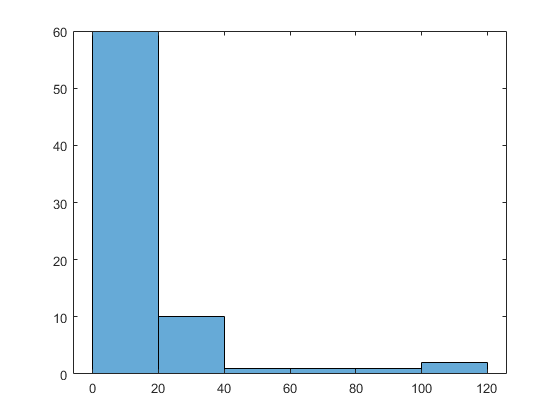


figure(2)
histogram(data_buero.Zyklen)

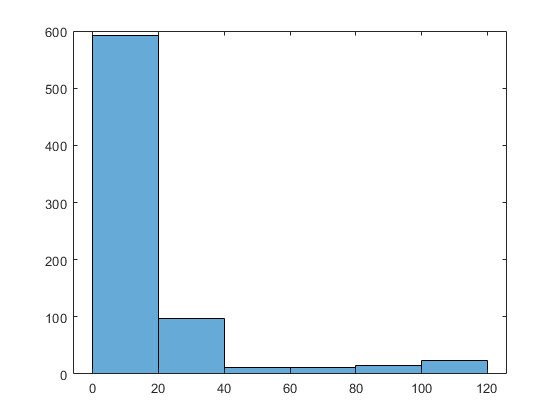


histogram(data_buero.Zyklen(data_boot_buero),6)


% Wasser MSA1 b)
data_msa = readtable('MSA_Verfahren1_200ml_Jan.csv')

data_msa = 25×1 table
    Gewicht_in_g
    ____________

    199         
    213         
    185         
    198         
    205         
    191         
    184         
    193         
    199         
    206         
    207         
    210         
    213         
    197         
    205         
    203         



pd_norm_msa = fitdist(data_msa.Gewicht_in_g, 'Normal')

pd_norm_msa =   NormalDistribution

  Normal distribution
       mu =  200.04   [196.787, 203.293]
    sigma = 7.88184   [6.15436, 10.9648]


ci_normal_msa = paramci(pd_norm_msa, 'Alpha', 0.05)

ci_normal_msa =   196.7865    6.1544
  203.2935   10.9648



[~,~,t_ci_msa,t_stats_msa] = ttest(data_msa.Gewicht_in_g)

t_ci_msa =   196.7865
  203.2935


t_stats_msa = struct with fields:
    tstat: 126.8994
       df: 24
       sd: 7.8818



pd_wybul_msa = fitdist(data_msa.Gewicht_in_g,'Weibull')

pd_wybul_msa =   WeibullDistribution

  Weibull distribution
    A =  203.71   [200.821, 206.64]
    B = 29.0413   [21.4884, 39.2491]


ci_wybul_msa = paramci(pd_wybul_msa, 'Alpha', 0.05)

ci_wybul_msa =   200.8207   21.4884
  206.6400   39.2491



[boot_msa, data_boot_msa]=bootstrp(1000,@median,data_msa.Gewicht_in_g)

boot_msa =    204
   198
   199
   199
   199
   198
   199
   206
   197
   207


data_boot_msa =     10    13     9    16    24    25    12    13     3    10    17    17    22    16     3    14    23     8     7     9     8     7     2     5    23    19    10    23    10    16     3    13     4    22    10    22    25    16     2     1    10    14    12    20    24    15     8    22     5    12
     3    19     7     2    15     9    22    13    17    23    10    23    17    12    14    20    13    23    24    12    11     8    18     6    19     1    15    25    24    10     6     7    23     9    20    20    16    13    19     7    13    24     6    17    17    13     4    19    25    19
     7     4    16     7    14    14    22    23    21    22    16    10    21    13     5     7     2    25    19    19    25    11     2    23    25    15    16    12    17    18     8    11     7    23    13    18    11    19     3    21    12     2    13     9    12    24     5    21     4    11
    20     8    20     3    10     3    10    12    19    16     3    14    20   

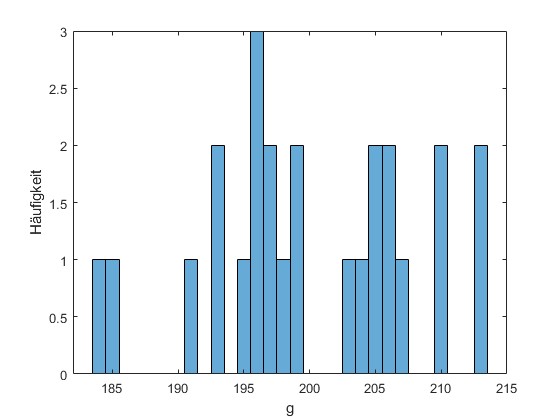



histogram(data_msa.Gewicht_in_g)
xlabel("g")
ylabel("Häufigkeit")

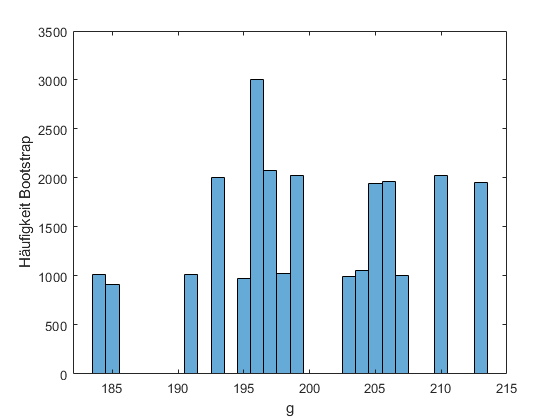

histogram(data_msa.Gewicht_in_g(data_boot_msa))
xlabel("g")
ylabel("Häufigkeit Bootstrap")

% Aufgabe 2
% Medikament hat keine Auswirkung auf Cholesterin
data_cholesterin_senker = readtable('cholesterinsenker.csv')

data_cholesterin_senker = 10×2 table
     A      B 
    ___    ___

      0    -22
    -27    -14
    -16    -15
    -13    -32
     -6    -22
    -27    -34
     -5    -38
    -22    -16
     -9    -25
     -3    -26


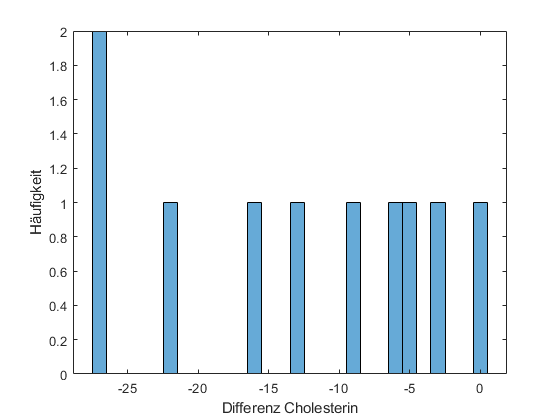


histogram(data_cholesterin_senker.A)
xlabel("Differenz Cholesterin")
ylabel("Häufigkeit")


[h,p,ci,s] = ttest2(data_cholesterin_senker.A,data_cholesterin_senker.B,'Alpha',0.01)

h = 0

p = 0.0107

ci =    -0.1355
   23.3355


s = struct with fields:
    tstat: 2.8452
       df: 18
       sd: 9.1165


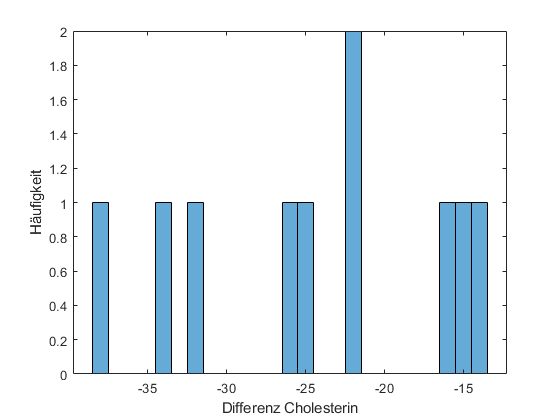



histogram(data_cholesterin_senker.B)
xlabel("Differenz Cholesterin")
ylabel("Häufigkeit")


boxplot(x(:,1),x(:,2),'Notch','on','Labels',{'Kontrollgruppe','Didgeridoo'})

Undefined function or variable 'x'.